# **Week 7 : Optical Channel with 16QAM**

The code below implements an optical system with 16QAM with DSPs, and aims to investigate the feasibility of the model and the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using 16QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

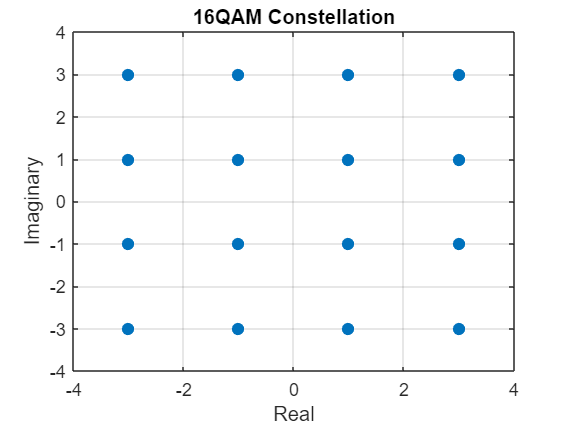

k = 4

symbols =   -3.0000 + 3.0000i  -3.0000 + 1.0000i  -3.0000 - 3.0000i  -3.0000 - 1.0000i  -1.0000 + 3.0000i  -1.0000 + 1.0000i  -1.0000 - 3.0000i  -1.0000 - 1.0000i   3.0000 + 3.0000i   3.0000 + 1.0000i   3.0000 - 3.0000i   3.0000 - 1.0000i   1.0000 + 3.0000i   1.0000 + 1.0000i   1.0000 - 3.0000i   1.0000 - 1.0000i


clear all; clearvars;

% Modulation parameters
M = 16; % Modulation order

% Visualising constellation
[k, symbols] = PlotConstellation("16QAM", 0) 


% Generating random bit sequence(s)
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
NSequences = 15; % No. of bit sequences

sourceBits = randi([0 1], NSymb*k, NSequences) % Matrix of source bits

sourceBits =      1     1     0     1     0     1     1     0     0     1     1     1     0     0     1
     1     1     0     0     0     1     0     1     1     0     0     1     1     0     0
     1     0     1     1     0     1     0     1     1     1     1     1     0     1     1
     0     0     0     0     0     0     0     1     0     1     0     1     0     0     1
     1     0     1     1     0     1     1     1     0     0     0     0     1     0     0
     1     1     1     0     1     0     0     1     1     1     0     1     1     1     1
     0     1     0     1     0     0     0     1     1     0     0     0     1     1     0
     0     0     0     0     1     0     0     0     0     1     0     1     1     1     1
     1     0     0     1     0     0     1     1     0     0     1     1     1     0     0
     0     1     0     0     0     0     0     1     0     1     0     1     1     0     0


sourceInts = bit2int(sourceBits, k)

sourceInts =     14    12     2    10     0    14     8     7     6    11    10    15     4     2    11
    12     6    12    10     5     8     8    14     6     5     0     5    15     7     5
     8     7     2    11     2     3    10    14     3     4     9    15    14     3     0
    12    11    12    10     7    14     1     4    10     3     2     5    15    13    12
    14    14    15    10    13     3     0     6     4     7     1     0     3     9    13
     8     3     8    13     0     5     6     4    10     2     3     5    12     4    14
     2     4     4    13    14     1     0     9    12     9     6     3     1    12    10
     9    15    14     8    10    10     8    15    14     6     9    11    10    14     2
     8     9     0     6     4    13    12     5     3     9     7     8    14    12    15
     1     0     8     9     7    10     3     0     3    10     5    12     4    15    12


sourceSymbols = qammod(sourceInts, M) % Maps source bit vector to symbol vector

sourceSymbols =    1.0000 - 3.0000i   1.0000 + 3.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i  -3.0000 + 3.0000i   1.0000 - 3.0000i   3.0000 + 3.0000i  -1.0000 - 1.0000i  -1.0000 - 3.0000i   3.0000 - 1.0000i   3.0000 - 3.0000i   1.0000 - 1.0000i  -1.0000 + 3.0000i  -3.0000 - 3.0000i   3.0000 - 1.0000i
   1.0000 + 3.0000i  -1.0000 - 3.0000i   1.0000 + 3.0000i   3.0000 - 3.0000i  -1.0000 + 1.0000i   3.0000 + 3.0000i   3.0000 + 3.0000i   1.0000 - 3.0000i  -1.0000 - 3.0000i  -1.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i
   3.0000 + 3.0000i  -1.0000 - 1.0000i  -3.0000 - 3.0000i   3.0000 - 1.0000i  -3.0000 - 3.0000i  -3.0000 - 1.0000i   3.0000 - 3.0000i   1.0000 - 3.0000i  -3.0000 - 1.0000i  -1.0000 + 3.0000i   3.0000 + 1.0000i   1.0000 - 1.0000i   1.0000 - 3.0000i  -3.0000 - 1.0000i  -3.0000 + 3.0000i
   1.0000 + 3.0000i   3.0000 - 1.0000i   1.0000 + 3.0000i   3.0000 - 3.0000i  -1.0000 - 1.0000i   1.0000 - 3.0000i  -3.0000 + 

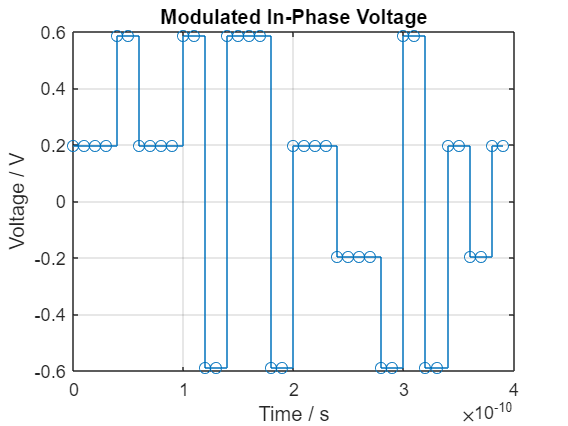


% 16QAM mapping

T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Modulating voltage with generated symbols
DCOffset = 0; % DC offset of modulated current in V
Vmax = 1; % Sets the maximum value of the voltage
voltageLevels = [-3*pi/16, -pi/16, pi/16, 3*pi/16]';

vI = ones(size(sourceSymbols));
vQ = ones(size(sourceSymbols));

% Mapping the distinct real & imaginary values to their respective voltage levels
vI(real(sourceSymbols)<=-2) = voltageLevels(1); 
vI(real(sourceSymbols)>-2 & real(sourceSymbols)<=0) = voltageLevels(2);
vI(real(sourceSymbols)>0 & real(sourceSymbols)<=2) = voltageLevels(3); 
vI(real(sourceSymbols)>2) = voltageLevels(4); 

vQ(imag(sourceSymbols)<=-2) = voltageLevels(1); 
vQ(imag(sourceSymbols)>-2 & imag(sourceSymbols)<=0) = voltageLevels(2);
vQ(imag(sourceSymbols)>0 & imag(sourceSymbols)<=2) = voltageLevels(3); 
vQ(imag(sourceSymbols)>2) = voltageLevels(4); 

vIupsampled = repelem(vI, SpS, 1); % Upsampling the voltage waveform based on SpS
vQupsampled = repelem(vQ, SpS, 1); % Upsampling the voltage waveform based on SpS

% Visualising in-phase and quadrature voltages
stairs(t(1:20*SpS), vIupsampled(1:20*SpS,1), "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

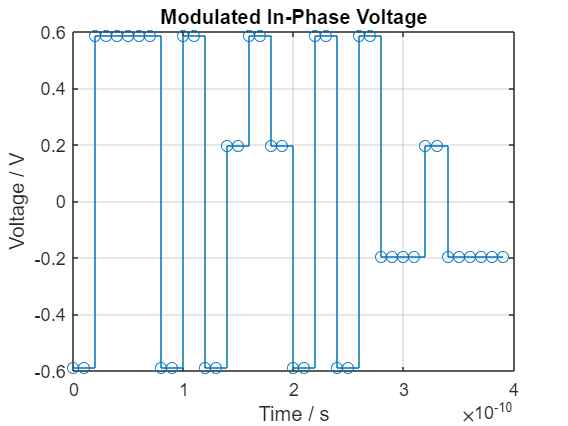


stairs(t(1:20*SpS), vQupsampled(1:20*SpS,1), "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

### Adding AWGN

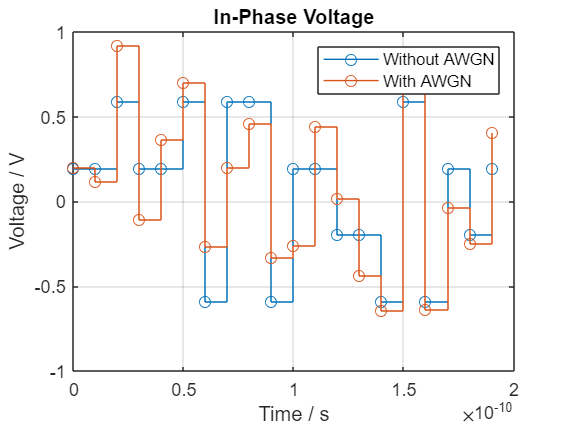

% Adding AWGN to the voltage waveforms before pulse shaping

SNRb_dB = [0:NSequences-1]'; % SNR per bit in dB
powerPerSymb = mean(voltageLevels.^2);
powerPerBit= powerPerSymb/k; 

vUpsampled_AWGN = zeros(size(vIupsampled)); % Noisy signal to be continued without shaping
v_AWGN = zeros(size(vI)); % Noisy signal to be shaped 
for i=1:NSequences
    SNRb_Lin(i,1) = 10^(SNRb_dB(i,1)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerSymb/SNRb_Lin(i,1)); % AWGN Standard deviation
    % v_AWGN(:,i) = (vI(:,i)+1i*vQ(:,i)) + (1/sqrt(2))*(AWGN_StdDev(i,1)*randn(size(v_AWGN,1),1) + 1i*AWGN_StdDev(i,1)*randn(size(v_AWGN,1),1));
    % vUpsampled_AWGN(:,i) = (vIupsampled(:,i)+1i*vQupsampled(:,i)) + + (1/sqrt(2))*(AWGN_StdDev(i,1)*randn(size(vUpsampled_AWGN,1),1) + 1i*AWGN_StdDev(i,1)*randn(size(vUpsampled_AWGN,1),1));

    % Using in-built awgn function
    v_AWGN(:,i) = awgn(vI(:,i)+1i*vQ(:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=k), 'measured');
    vUpsampled_AWGN(:,i) = awgn(vIupsampled(:,i)+1i*vQupsampled(:,i), convertSNR(SNRb_dB(i),'ebno', samplespersymbol=1, bitspersymbol=k), 'measured');
`end

% Debugging AWGN addition
% Visualising in-phase voltage with and without noise
stairs(t(1:10*SpS), vI(1:10*SpS,1), '-o');
hold on 
stairs(t(1:10*SpS), real(v_AWGN(1:10*SpS,1)), '-o');
title("In-Phase Voltage");
xlabel("Time / s");
ylabel("Voltage / V");
legend("Without AWGN", "With AWGN");
grid on
hold off

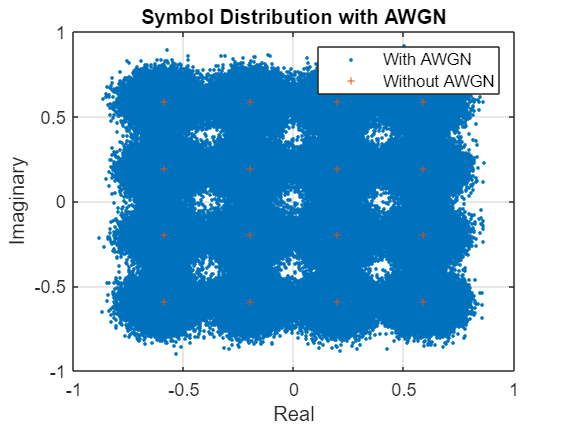


% Visualising symbol distribution with and without noise 
plot(v_AWGN(:,11), '.');
hold on
plot(vI(:,11), vQ(:,11), '+', MarkerSize=4);
title("Symbol Distribution with AWGN");
xlabel("Real");
ylabel("Imaginary");
legend("With AWGN", "Without AWGN");
grid on
hold off


% Premature decoding to check validity of AWGN model
% tempInts = pskdemod(vUpsampled_AWGN, M);
% tempBits = int2bit(tempInts, k);
% 
% for i=1:NSequences
%     [~, tempBER(i,1)] = biterr(sourceBits(:,i), downsample(tempBits(:,i), SpS));
% end
% 
% % Visualising BER vs SNR plot
% semilogy(SNRb_dB(1:11), 0.5*erfc(sqrt(10.^(SNRb_dB(1:11)/10))));
% hold on
% semilogy(SNRb_dB, tempBER, "-o");
% title("BER vs SNR");
% xlabel("SNR per bit / dB");
% ylabel("BER");
% legend("Theoretical", "Simulation")
% grid on
% hold off



### Pulse Shaping

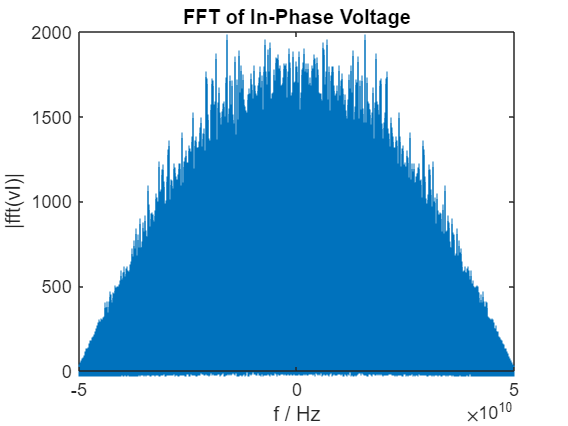

% Frequency spectrum of voltage waveform before filtering
fft_vI = fftshift(fft(vIupsampled(:,11))); % FFT without AWGN
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
stem(freqArr, abs(fft_vI), "|");
title("FFT of In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(vI)|");

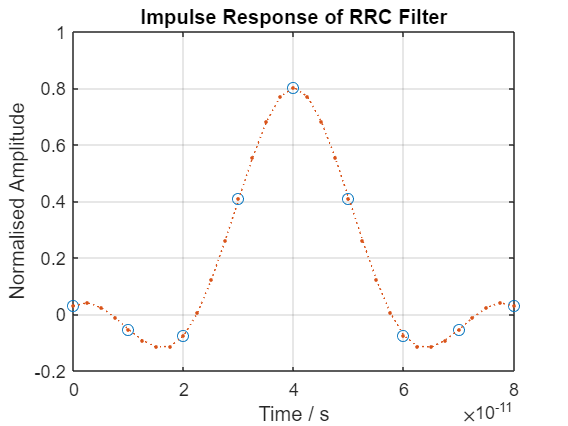


% RRC filter
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

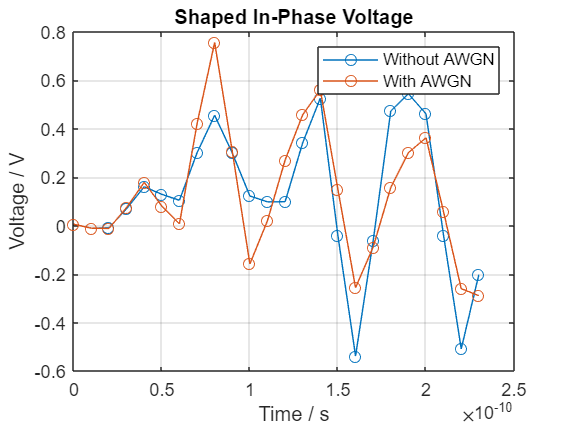


% Using RC filter to shape vI and vQ
% Without AWGN
vI_shaped = upfirdn(vI, filterResponse, SpS, 1); vQ_shaped = upfirdn(vQ, filterResponse, SpS, 1);
% With AWGN
vI_shaped_AWGN = upfirdn(real(v_AWGN), filterResponse, SpS, 1); vQ_shaped_AWGN = upfirdn(imag(v_AWGN), filterResponse, SpS, 1);


% Visualising pulse-shaped voltages
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;
plot(v_shaped_t(1:10*SpS + filterSpan), vI_shaped(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), real(vI_shaped_AWGN(1:10*SpS + filterSpan,1)), "o-");
title("Shaped In-Phase Voltage");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Without AWGN", "With AWGN");
grid on
hold off

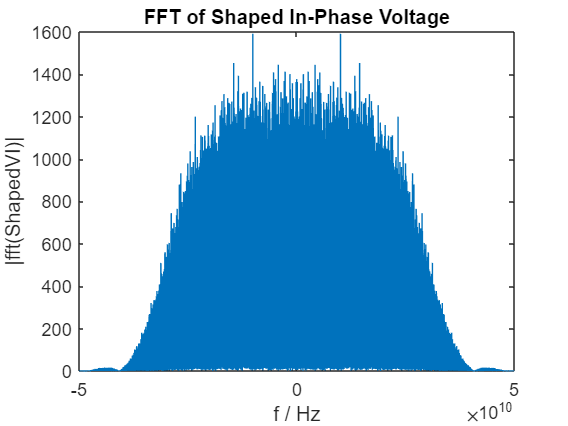

% Frequency spectrum of voltage waveform after filtering
fft_vI_shaped = fftshift(fft(vI_shaped(:,1)));
freqArr = [-samples/2:samples/2 - 1]/(T*samples);
plot(freqArr, abs(fft_vI_shaped));
title("FFT of Shaped In-Phase Voltage");
xlabel("f / Hz");
ylabel("|fft(ShapedVI)|");
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10


% Eye diagram of voltage waveform before filtering
% eyediagram(vI(1:1000,1), SpS);
% title("Eye Diagram of Discrete In-Phase Voltage")
% eyediagram(shapedVI(1:1000,1), SpS);
% title("Eye Diagram of Pulse-Shaped In-Phase Voltage")

### IQ Modulation

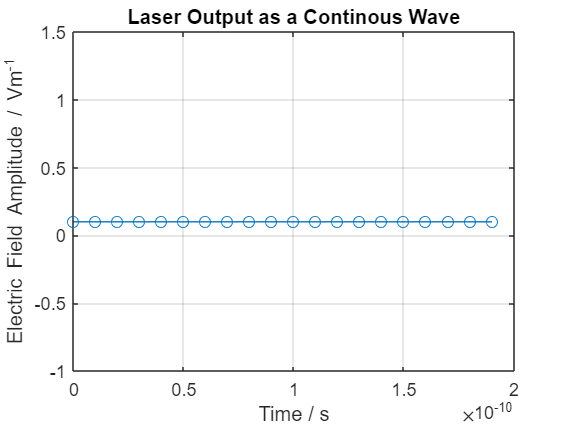

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 10;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);
laserEMag = sqrt(laserPw_Lin);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
t_interp = [0:0.25:NSymb*SpS - 1]*T;
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time / s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

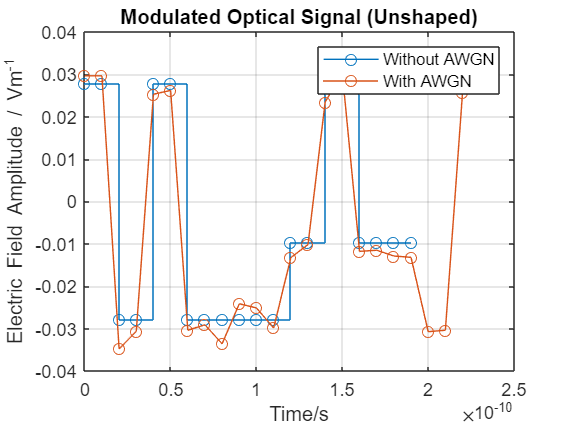


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi
modOpticSig = IQModulatorModified(vIupsampled, vQupsampled, laserE, Vpi);
modOpticSig_AWGN = IQModulatorModified(real(vUpsampled_AWGN), imag(vUpsampled_AWGN), laserE, Vpi);
modOpticSig_shaped = IQModulatorModified(vI_shaped, vQ_shaped, laserE_shaped, Vpi);
modOpticSig_shaped_AWGN = IQModulatorModified(vI_shaped_AWGN, vQ_shaped_AWGN, laserE_shaped, Vpi);

% Visualising modulated optic signals
stairs(t(1:10*SpS), real(modOpticSig(1:10*SpS,11)), "o-");
hold on
plot(t(1:10*SpS+ filterSpan), real(modOpticSig_AWGN(1:10*SpS+ filterSpan, 11)), "o-");
title("Modulated Optical Signal (Unshaped)")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Without AWGN", "With AWGN")
grid on
hold off

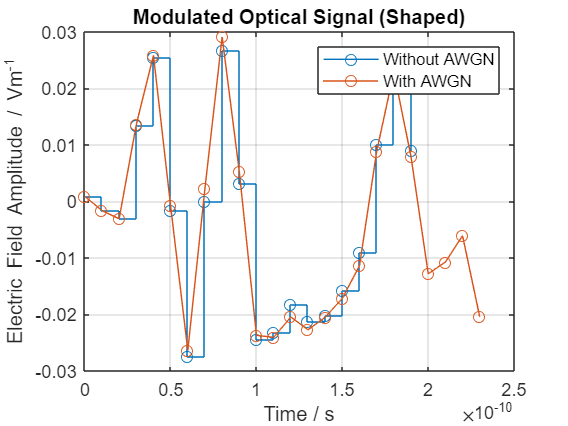


stairs(t(1:10*SpS), real(modOpticSig_shaped(1:10*SpS,11)), "o-");
hold on
plot(t(1:10*SpS+ filterSpan), real(modOpticSig_shaped_AWGN(1:10*SpS+ filterSpan, 11)), "o-");
title("Modulated Optical Signal (Shaped)")
xlabel("Time / s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Without AWGN", "With AWGN")
grid on
hold off

## Receiver

### Optical Front-End

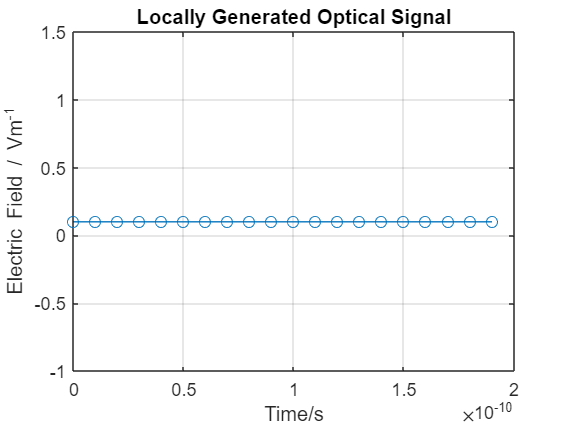

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source
Elo_shaped = laserE_shaped;

% Visualising locally generated optical signal
plot(t(1:20), real(Elo(1:20,1)), "-o");
title("Locally Generated Optical Signal")
xlabel("Time/s")
ylabel("Electric Field / Vm^{-1}")
grid on

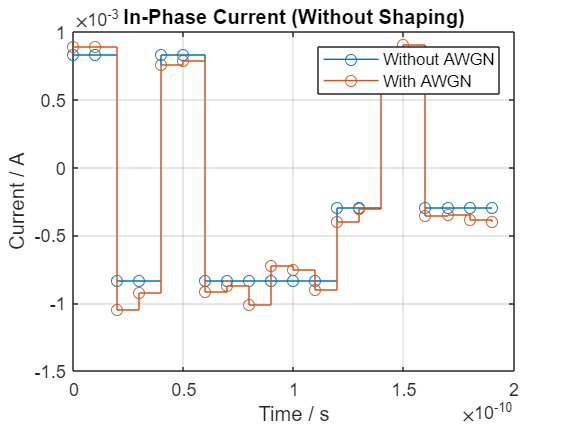


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count = 1;

for i=1:size(modOpticSig,2)
    % Output from Optical Front-End
    OpticFEOut(:,count:count+1) = OpticalFrontEnd(modOpticSig(:,i), Elo, eta_ph, 1);
    OpticFEOut_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_AWGN(:,i), Elo, eta_ph, 1);
    OpticFEOut_shaped(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped(:,i), Elo_shaped, eta_ph, 1);
    OpticFEOut_shaped_AWGN(:,count:count+1) = OpticalFrontEnd(modOpticSig_shaped_AWGN(:,i), Elo_shaped, eta_ph, 1);
    count = count+2;
end

stairs(t(1:10*SpS), OpticFEOut(1:10*SpS,21), "-o"); % In-phase current
hold on
stairs(t(1:10*SpS), OpticFEOut_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (Without Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off

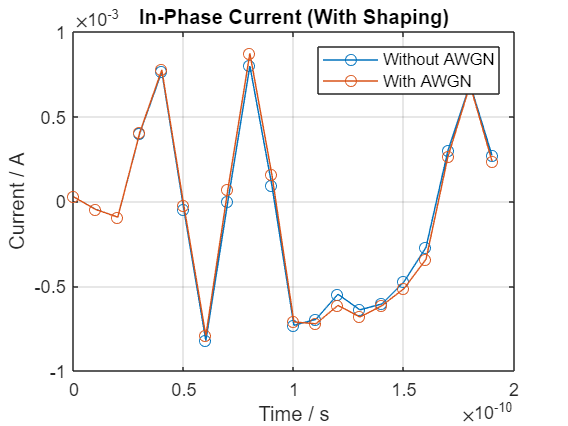


plot(t(1:10*SpS), OpticFEOut_shaped(1:10*SpS,21), "-o"); % In-phase current
hold on
plot(t(1:10*SpS), OpticFEOut_shaped_AWGN(1:10*SpS,21), "-o")
title("In-Phase Current (With Shaping)")
xlabel("Time / s")
ylabel("Current / A")
legend("Without AWGN", "With AWGN")
grid on
hold off


% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
voltageI = TIA_Gain*OpticFEOut(1:SpS:end, 1:2:end); voltageI_AWGN = TIA_Gain*OpticFEOut_AWGN(1:SpS:end, 1:2:end);
voltageQ = TIA_Gain*OpticFEOut(1:SpS:end, 2:2:end); voltageQ_AWGN = TIA_Gain*OpticFEOut_AWGN(1:SpS:end, 2:2:end);
OpticalFEOut_I_shaped = TIA_Gain*OpticFEOut_shaped(:, 1:2:end); OpticalFEOut_I_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 1:2:end);
OpticalFEOut_Q_shaped = TIA_Gain*OpticFEOut_shaped(:, 2:2:end); OpticalFEOut_Q_shaped_AWGN = TIA_Gain*OpticFEOut_shaped_AWGN(:, 2:2:end);

% Passing shaped components through matched filter and downsampling
voltageI_shaped = upfirdn(OpticalFEOut_I_shaped, filterResponse, 1, SpS); voltageI_shaped = voltageI_shaped(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped = upfirdn(OpticalFEOut_Q_shaped, filterResponse, 1, SpS); voltageQ_shaped = voltageQ_shaped(filterSpan + 1:end - filterSpan,:);
voltageI_shaped_AWGN = upfirdn(OpticalFEOut_I_shaped_AWGN, filterResponse, 1, SpS); voltageI_shaped_AWGN = voltageI_shaped_AWGN(filterSpan + 1:end - filterSpan,:);
voltageQ_shaped_AWGN = upfirdn(OpticalFEOut_Q_shaped_AWGN, filterResponse, 1, SpS); voltageQ_shaped_AWGN = voltageQ_shaped_AWGN(filterSpan + 1:end - filterSpan,:);


## DSP

### Decision and Decoding

% Downscaling voltage values
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2; % Scale factor

voltageI = asin(voltageI/scaleFactor); voltageQ = asin(voltageQ/scaleFactor);
voltageI_AWGN = asin(voltageI_AWGN/scaleFactor); voltageQ_AWGN = asin(voltageQ_AWGN/scaleFactor);
voltageI_shaped = asin(voltageI_shaped/scaleFactor); voltageQ_shaped = asin(voltageQ_shaped/scaleFactor);
voltageI_shaped_AWGN = asin(voltageI_shaped_AWGN/scaleFactor); voltageQ_shaped_AWGN = asin(voltageQ_shaped_AWGN/scaleFactor);

% Converting from downscaled voltage values to original symbols
voltageI = voltageI/(pi/16); voltageQ = voltageQ/(pi/16);
voltageI_AWGN = voltageI_AWGN/(pi/16); voltageQ_AWGN = voltageQ_AWGN/(pi/16);
voltageI_shaped = voltageI_shaped/(pi/16); voltageQ_shaped = voltageQ_shaped/(pi/16);
voltageI_shaped_AWGN = voltageI_shaped_AWGN/(pi/16); voltageQ_shaped_AWGN = voltageQ_shaped_AWGN/(pi/16);

% Manual decision and decoding based on intermediate values
% tempI = zeros(size(voltageI));
% tempI(voltageI <= -2*pi/16) = -3;
% tempI(voltageI > -2*pi/16 & voltageI <= 0) = -1;
% tempI(voltageI > 0 & voltageI <= 2*pi/16) = 1;
% tempI(voltageI > 2*pi/16) = 3;
% 
% tempQ = zeros(size(voltageQ));
% tempQ(voltageQ <= -2*pi/16) = -3;
% tempQ(voltageQ > -2*pi/16 & voltageQ <= 0) = -1;
% tempQ(voltageQ > 0 & voltageQ <= 2*pi/16) = 1;
% tempQ(voltageQ > 2*pi/16) = 3;


% Mapping scaled voltages to inital in-phase component of the symbol
% constellation.
% Quadrature component is ignored as it is the same value for all symbols.
% Maximum likelihood estimation, based on the Euclidian distance between the recieved voltage points
% and those corresponding to the symbols, is used.
sourceSymbols;
voltageI;
decodedSymbols = voltageI + 1i*voltageQ

decodedSymbols =    1.0000 - 3.0000i   1.0000 + 3.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i  -3.0000 + 3.0000i   1.0000 - 3.0000i   3.0000 + 3.0000i  -1.0000 - 1.0000i  -1.0000 - 3.0000i   3.0000 - 1.0000i   3.0000 - 3.0000i   1.0000 - 1.0000i  -1.0000 + 3.0000i  -3.0000 - 3.0000i   3.0000 - 1.0000i
   1.0000 + 3.0000i  -1.0000 - 3.0000i   1.0000 + 3.0000i   3.0000 - 3.0000i  -1.0000 + 1.0000i   3.0000 + 3.0000i   3.0000 + 3.0000i   1.0000 - 3.0000i  -1.0000 - 3.0000i  -1.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i
   3.0000 + 3.0000i  -1.0000 - 1.0000i  -3.0000 - 3.0000i   3.0000 - 1.0000i  -3.0000 - 3.0000i  -3.0000 - 1.0000i   3.0000 - 3.0000i   1.0000 - 3.0000i  -3.0000 - 1.0000i  -1.0000 + 3.0000i   3.0000 + 1.0000i   1.0000 - 1.0000i   1.0000 - 3.0000i  -3.0000 - 1.0000i  -3.0000 + 3.0000i
   1.0000 + 3.0000i   3.0000 - 1.0000i   1.0000 + 3.0000i   3.0000 - 3.0000i  -1.0000 - 1.0000i   1.0000 - 3.0000i  -3.0000 +

decodedInts = qamdemod(decodedSymbols, M);
decodedBits = int2bit(decodedInts, k);
biterr(decodedBits, sourceBits)

ans = 0


decodedSymbols_AWGN = voltageI_AWGN + 1i*voltageQ_AWGN;
vUpsampled_AWGN;
decodedInts_AWGN = qamdemod(decodedSymbols_AWGN, M);
decodedBits_AWGN = int2bit(decodedInts_AWGN, k);

decodedSymbols_shaped = voltageI_shaped + 1i*voltageQ_shaped;
decodedInts_shaped= qamdemod(decodedSymbols_shaped, M);
decodedBits_shaped = int2bit(decodedInts_shaped, k);
biterr(decodedBits_shaped, sourceBits)

ans = 0

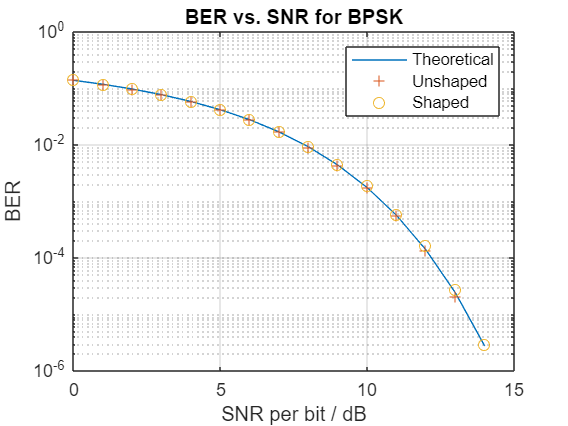


decodedSymbols_shaped_AWGN = voltageI_shaped_AWGN + 1i*voltageQ_shaped_AWGN;
decodedInts_shaped_AWGN= qamdemod(decodedSymbols_shaped_AWGN, M);
decodedBits_shaped_AWGN = int2bit(decodedInts_shaped_AWGN, k);

BER_BPSK_AWGN = zeros(NSequences,1); numErrors = zeros(NSequences,1);
BER_BPSK_AWGN_shaped = zeros(NSequences,1); numErrors_shaped = zeros(NSequences,1);

for i=1:NSequences
    [numErrors(i,1), BER_BPSK_AWGN(i,1)] = biterr(sourceBits(:,i), decodedBits_AWGN(:,i));
    [numErrors_shaped(i,1), BER_BPSK_AWGN_shaped(i,1)] = biterr(sourceBits(:,i), decodedBits_shaped_AWGN(:,i));
end


semilogy(SNRb_dB, (3/8)*erfc(sqrt(SNRb_Lin*2/5)));
hold on
semilogy(SNRb_dB, BER_BPSK_AWGN, '+');
semilogy(SNRb_dB, BER_BPSK_AWGN_shaped, 'o');
title("BER vs. SNR for BPSK");
ylabel("BER");
xlabel("SNR per bit / dB");
legend("Theoretical", "Unshaped", "Shaped");
grid on
hold off


% save("BPSKData.mat","SNRb_dB", "BER_BPSK")